# **3D Rocket Trajectory Simulation**

clc;
clear;
close all;
disp('Welcome to the project: 3D Rocket Trajectory Simulation');

Welcome to the project: 3D Rocket Trajectory Simulation


**Rocket Parameters:**

m_cohete = input('Enter the structural mass of the rocket (kg): ');
m_combustible = input('Enter the mass of the fuel (kg): ');
g = 9.81;
rho0 = 1.225;
Cd = 0.75;
thrust = input('Enter the thrust applied to the rocket (N): ');
dt = 0.1;
H = 8442;
latitud = input('Enter the launch site latitude (degrees): ');
V_wind = input('Enter the crosswind speed (m/s): ');
theta_wind = input('Enter the crosswind direction (degrees): ');

**Rocket Geometry:**

diameter = input('Enter the rocket diameter (m): ');
height = input('Enter the rocket height (m): ');
A = pi * (diameter / 2)^2;

disp('Select the rocket nose cone shape:');

Select the rocket nose cone shape:


disp('1. Conical');

1. Conical


disp('2. Ogive');

2. Ogive


disp('3. Parabolic');

3. Parabolic


disp('4. Hemispherical');

4. Hemispherical


nose_choice = input('Enter the corresponding number: ');

if nose_choice == 1
    nose_shape = "conical";
elseif nose_choice == 2
    nose_shape = "ogive";
elseif nose_choice == 3
    nose_shape = "parabolic";
elseif nose_choice == 4
    nose_shape = "hemispherical";
end 

fprintf('Selected nose shape: %s\n', nose_shape);

Selected nose shape: conical


**Propellant:**


disp('Select the type of propellant:')

Select the type of propellant:


disp('1. Liquid Hydrogen (LH2 + LOX) - Isp: 430 s');

1. Liquid Hydrogen (LH2 + LOX) - Isp: 430 s


disp('2. RP-1 (kerosene) + LOX - Isp: 300 s');

2. RP-1 (kerosene) + LOX - Isp: 300 s


disp('3. Ammonium Perchlorate (AP) + Aluminum - Isp: 250 s');

3. Ammonium Perchlorate (AP) + Aluminum - Isp: 250 s


disp('4. Nitrous Oxide (N2O) + HTPB - Isp: 300 s');

4. Nitrous Oxide (N2O) + HTPB - Isp: 300 s


fuel_type = input('Enter the number corresponding to the propellant: ');

switch fuel_type
    case 1
        Isp = 430;
    case 2
        Isp = 300;
    case 3
        Isp = 250;
    case 4
        Isp = 300;
    otherwise
        Isp = 300;
end
burn_time = (m_combustible * Isp * g)/thrust;

**Launch Angle:**

theta_z = input('Enter the elevation angle (Z) in degrees: ');
theta_xy = input('Enter the angle in the XY plane in degrees: ');

**Calculate the initial drag coefficient (Cd0):**

v0 = 0.1;
alpha = 0;
num_fins = 4;
Cd0 = calculate_Cd0(nose_shape, diameter, height, num_fins, alpha, v0, rho0);
fprintf('Initial drag coefficient (Cd0): %.4f\n', Cd0);

Initial drag coefficient (Cd0): 0.4732


**Simulation Parameters Summary:**

disp('-- Simulation Parameters Summary --');

-- Simulation Parameters Summary --


fprintf('Rocket structural mass: %.2f kg\n', m_cohete);

Rocket structural mass: 200000.00 kg


fprintf('Fuel mass: %.2f kg\n', m_combustible);

Fuel mass: 3200000.00 kg


fprintf('Thrust: %.2f N\n', thrust);

Thrust: 72000000.00 N


fprintf('Estimated burn time: %.2f s\n', m_combustible / (thrust / (Isp * g)));

Estimated burn time: 109.00 s


fprintf('Isp: %.2f s\n', Isp);

Isp: 250.00 s


fprintf('Nose shape: %s\n', nose_shape);

Nose shape: conical


fprintf('Rocket diameter: %.2f m\n', diameter);

Rocket diameter: 9.00 m


fprintf('Rocket height: %.2f m\n', height);

Rocket height: 69.00 m


fprintf('Latitude: %.2f°\n', latitud);

Latitude: 25.99°


fprintf('Wind speed: %.2f m/s\n', V_wind);

Wind speed: 15.40 m/s


fprintf('Wind direction: %.2f°\n', theta_wind);

Wind direction: 135.00°


fprintf('Launch angle (Z axis): %.2f°\n', theta_z);

Launch angle (Z axis): 85.00°


fprintf('Launch angle in XY plane: %.2f°\n', theta_xy);

Launch angle in XY plane: 15.30°


fprintf('Initial drag coefficient (Cd0): %.4f\n', Cd0);

Initial drag coefficient (Cd0): 0.4732


disp('-------------------------------------');

-------------------------------------


**Run Simulation:**

try 
    trajectory = simulate_rocket_3d(m_cohete, m_combustible, g, rho0, Cd0, A, thrust, burn_time, dt, theta_z, theta_xy, Isp, nose_shape, diameter, latitud, V_wind, theta_wind);
    fprintf('Simulation completed successfully.\n');
catch ME
    fprintf('Error during simulation: %s\n', ME.message);
    return;
end

Simulation completed successfully.


**3D Trajectory Visualization:**

Generating 3D visualization...


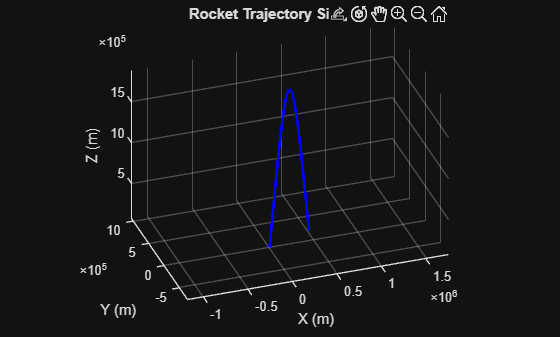

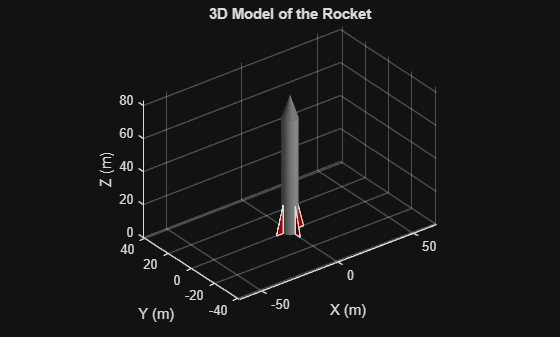

try
    disp('Generating 3D visualization...');
    radius = diameter / 2;
    nose_height = height * 0.2;
    simulate_and_draw_rocket3D(trajectory, radius, height, nose_height, nose_shape);
catch ME
    fprintf('Error during visualization: %s\n', ME.message);
    return;
end

**Position and Displacement:**

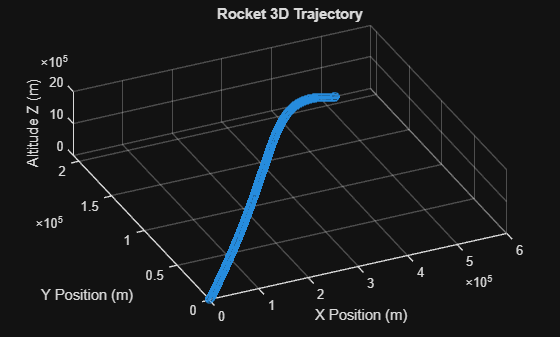

figure;
plot3(trajectory(:,1), trajectory(:,2), trajectory(:,3), '-o');
xlabel('X Position (m)');
ylabel('Y Position (m)');
zlabel('Altitude Z (m)');
title('Rocket 3D Trajectory');

grid on;
view(3);
exportgraphics(gcf, 'rocket_3D_trajectory.png', 'Resolution', 300);

**Summary of key trajectory points**

start_point = trajectory(1,:);
end_point = trajectory(end,:);
[~, idx_max_alt] = max(trajectory(:,3));
max_point = trajectory(idx_max_alt, :);

T = table(...
    ["Start"; "Max Altitude"; "End"], ...
    [start_point(1); max_point(1); end_point(1)], ...
    [start_point(2); max_point(2); end_point(2)], ...
    [start_point(3); max_point(3); end_point(3)], ...
    'VariableNames', {'Point', 'X (m)', 'Y (m)', 'Z (m)'});

disp('Summary of Key Trajectory Points:');

Summary of Key Trajectory Points:


disp(T);

        Point           X (m)         Y (m)         Z (m)   
    ______________    __________    __________    __________

    "Start"             0.017818     0.0048744       0.11304
    "Max Altitude"    2.6475e+05    1.0251e+05    1.8884e+06
    "End"             5.2851e+05    2.0883e+05       -42.656



**Velocity:**

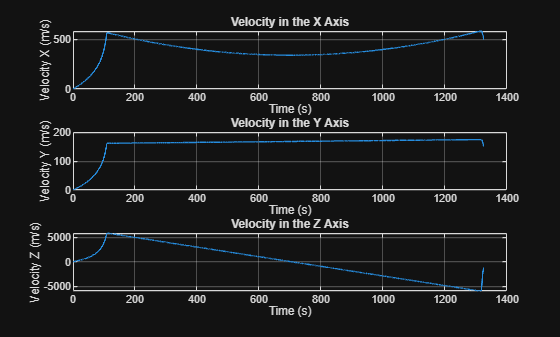

figure;
subplot(3,1,1);
plot(trajectory(:,4), gradient(trajectory(:,1), dt), '-');
xlabel('Time (s)');
ylabel('Velocity X (m/s)');
title('Velocity in the X Axis');
grid on; 

subplot(3,1,2);
plot(trajectory(:,4), gradient(trajectory(:,2), dt), '-');
xlabel('Time (s)');
ylabel('Velocity Y (m/s)');
title('Velocity in the Y Axis');
grid on;

subplot(3,1,3);
plot(trajectory(:,4), gradient(trajectory(:,3), dt), '-');
xlabel('Time (s)');
ylabel('Velocity Z (m/s)');
title('Velocity in the Z Axis');
grid on;

exportgraphics(gcf, 'velocity_XYZ.png', 'Resolution', 300);

**Velocity Event Analysis for All Axes**

vel_x_eq = zeros(size(trajectory, 1), 1);
vel_y_eq = zeros(size(trajectory, 1), 1);
vel_z_eq = zeros(size(trajectory, 1), 1);

for i = 2:size(trajectory, 1)
    ax = trajectory(i, 5);
    ay = trajectory(i, 6);
    az = trajectory(i, 7);

    vel_x_eq(i) = vel_x_eq(i-1) + ax * dt;
    vel_y_eq(i) = vel_y_eq(i-1) + ay * dt;
    vel_z_eq(i) = vel_z_eq(i-1) + az * dt;
end

axes_labels = ["X", "Y", "Z"];
velocities = {vel_x_eq, vel_y_eq, vel_z_eq};
results = [];

for i = 1:3
    v = velocities{i};
    [v_max, idx_max] = max(v);
    [v_min, idx_min] = min(v);
    idx_zero = find(abs(v) < 1e-3 & trajectory(:,4) > 0, 1);

    if isempty(idx_zero)
        t_zero = NaN;
        v_zero = NaN;
    else 
        t_zero = trajectory(idx_zero, 4);
        v_zero = v(idx_zero);
    end

    results = [results;
        {axes_labels(i), "Max Velocity", trajectory(idx_max, 4), v_max};
        {axes_labels(i), "Min Velocity", trajectory(idx_min, 4), v_min};
        {axes_labels(i), "Zero Crossing", t_zero, v_zero}];

    v_sign = sign(v);
    crossing_indices = find(diff(v_sign) ~= 0);

    for j = 1:length(crossing_indices)
        idx = crossing_indices(j) + 1;
        if trajectory(idx, 4) >= 0.5
            results = [results;
                {axes_labels(i), sprintf("Zero Crossing %d", j), trajectory(idx, 4), v(idx)}];
        end
    end
end

VelocitySummary = cell2table(results, ...
    'VariableNames', {'Axis', 'Event', 'Time (s)', 'Velocity (m/s)'});

disp('🔍 Summary of Velocity Events in Each Axis:');

🔍 Summary of Velocity Events in Each Axis:


disp(VelocitySummary);

    Axis          Event          Time (s)    Velocity (m/s)
    ____    _________________    ________    ______________

    "X"     "Max Velocity"        1316.2          583.14   
    "X"     "Min Velocity"             0               0   
    "X"     "Zero Crossing"          NaN             NaN   
    "Y"     "Max Velocity"        1313.4          174.08   
    "Y"     "Min Velocity"             0               0   
    "Y"     "Zero Crossing"          NaN             NaN   
    "Z"     "Max Velocity"           109          5841.1   
    "Z"     "Min Velocity"        1313.4         -6017.1   
    "Z"     "Zero Crossing"          NaN             NaN   
    "Z"     "Zero Crossing 2"      701.8        -0.41474   



**Acceleration:**

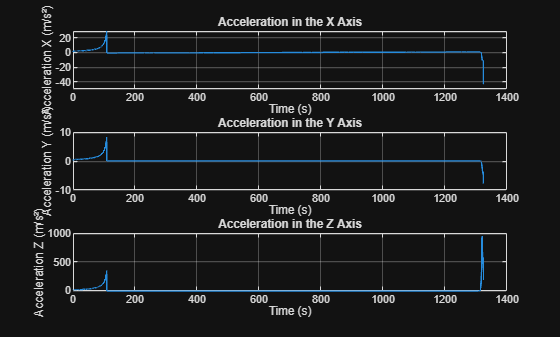

figure;
subplot(3,1,1);
plot(trajectory(:,4), gradient(gradient(trajectory(:,1), dt), dt), '-');
xlabel('Time (s)');
ylabel('Acceleration X (m/s²)');
title('Acceleration in the X Axis');
grid on;

subplot(3,1,2);
plot(trajectory(:,4), gradient(gradient(trajectory(:,2), dt), dt), '-');
xlabel('Time (s)');
ylabel('Acceleration Y (m/s²)');
title('Acceleration in the Y Axis');
grid on;

subplot(3,1,3);
plot(trajectory(:,4), gradient(gradient(trajectory(:,3), dt), dt), '-');
xlabel('Time (s)');
ylabel('Acceleration Z (m/s²)');
title('Acceleration in the Z Axis');
grid on;

exportgraphics(gcf, 'acceleration_XYZ.png', 'Resolution', 300);

**Acceleration Event Analysis for All Axes**

ax_eq = gradient(vel_x_eq, dt);
ay_eq = gradient(vel_y_eq, dt);
az_eq = gradient(vel_z_eq, dt);

axes_labels = ["X", "Y", "Z"];
accelerations = {ax_eq, ay_eq, az_eq};
accel_results = [];

for i = 1:3
    a = accelerations{i};
    [a_max, idx_max] = max(a);
    [a_min, idx_min] = min(a);

    accel_results = [accel_results;
        {axes_labels(i), "Max Acceleration", trajectory(idx_max, 4), a_max};
        {axes_labels(i), "Min Acceleration", trajectory(idx_min, 4), a_min}];
end

% Display acceleration summary
AccelerationSummary = cell2table(accel_results, ...
    'VariableNames', {'Axis', 'Event', 'Time (s)', 'Acceleration (m/s²)'});

disp('⚡ Summary of Acceleration Events in Each Axis:');

⚡ Summary of Acceleration Events in Each Axis:


disp(AccelerationSummary);

    Axis          Event           Time (s)    Acceleration (m/s²)
    ____    __________________    ________    ___________________

    "X"     "Max Acceleration"      108.9            29.499      
    "X"     "Min Acceleration"     1323.8           -44.154      
    "Y"     "Max Acceleration"      108.9            8.2896      
    "Y"     "Min Acceleration"     1323.8           -7.7534      
    "Z"     "Max Acceleration"     1319.8            947.84      
    "Z"     "Min Acceleration"      109.1           -9.8741      



**Velocity comparaison: Gradient vs. Equations**

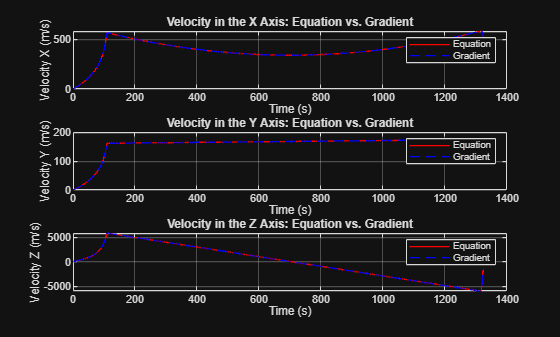

vel_x_eq = zeros(size(trajectory, 1), 1);
vel_y_eq = zeros(size(trajectory, 1), 1);
vel_z_eq = zeros(size(trajectory, 1), 1);

for i = 2:size(trajectory, 1)

    ax = trajectory(i, 5);
    ay = trajectory(i, 6);
    az = trajectory(i, 7);

    vel_x_eq(i) = vel_x_eq(i-1) + ax*dt;
    vel_y_eq(i) = vel_y_eq(i-1) + ay*dt;
    vel_z_eq(i) = vel_z_eq(i-1) + az*dt;
end

vel_x_grad = gradient(trajectory(:,1), dt);
vel_y_grad = gradient(trajectory(:,2), dt);
vel_z_grad = gradient(trajectory(:,3), dt);

figure;
subplot(3,1,1);
plot(trajectory(:,4), vel_x_eq, '-r', 'DisplayName', 'Equation');
hold on;
plot(trajectory(:,4), vel_x_grad, '--b', 'DisplayName', 'Gradient');
xlabel('Time (s)');
ylabel('Velocity X (m/s)');
title('Velocity in the X Axis: Equation vs. Gradient');
legend;
grid on;

subplot(3,1,2);
plot(trajectory(:,4), vel_y_eq, '-r', 'DisplayName', 'Equation');
hold on;
plot(trajectory(:,4), vel_y_grad, '--b', 'DisplayName', 'Gradient');
xlabel('Time (s)');
ylabel('Velocity Y (m/s)');
title('Velocity in the Y Axis: Equation vs. Gradient');
legend;
grid on;

subplot(3,1,3);
plot(trajectory(:,4), vel_z_eq, '-r', 'DisplayName', 'Equation');
hold on;
plot(trajectory(:,4), vel_z_grad, '--b', 'DisplayName', 'Gradient');
xlabel('Time (s)');
ylabel('Velocity Z (m/s)');
title('Velocity in the Z Axis: Equation vs. Gradient');
legend;
grid on;

**Simulation with and without crosswind**

disp('Simulating with crosswind...');

Simulating with crosswind...


trajectory_with_wind = simulate_rocket_3d(m_cohete, m_combustible, g, rho0, Cd0, A, thrust, burn_time, dt, theta_z, theta_xy, Isp, nose_shape, diameter, latitud, V_wind, theta_wind);

disp('Simulating without crosswind...');

Simulating without crosswind...


Generating comparison plots...


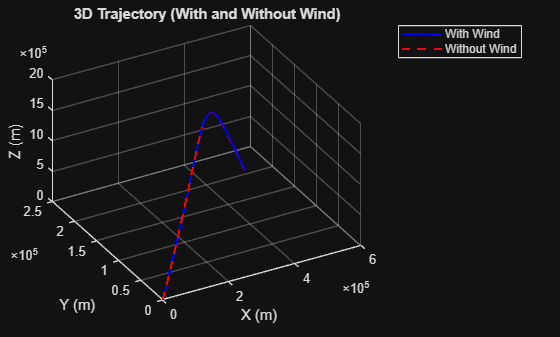

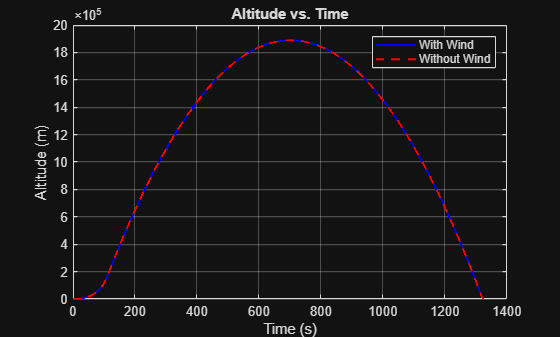

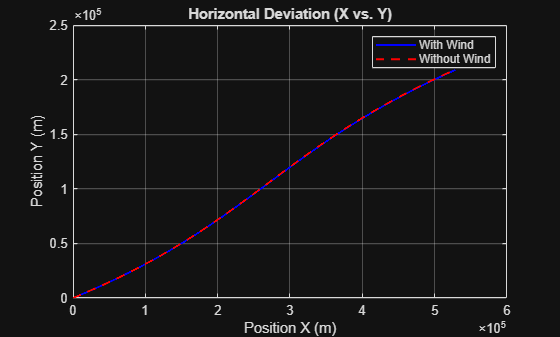

Comparison plots generated successfully.


trajectory_no_wind = simulate_rocket_3d(m_cohete, m_combustible, g, rho0, Cd0, A, thrust, burn_time, dt, theta_z, theta_xy, Isp, nose_shape, diameter, latitud, 0, 0);

min_length = min(size(trajectory_with_wind, 1), size(trajectory_no_wind, 1));
trajectory_with_wind = trajectory_with_wind(1:min_length, :);
trajectory_no_wind = trajectory_no_wind(1:min_length, :);

try
    disp('Generating comparison plots...');
    compare_wind_effect(trajectory_with_wind, trajectory_no_wind);
    fprintf('Comparison plots generated successfully.\n');
catch ME
    fprintf('Error while generating comparison plots: %s\n', ME.message);
end